# Pulse detector test bench (step 3)

© 2019-2020 The MathWorks, Inc.

This test bench creates a reference pulse detection algorithm, simulates the Simulink model implementation, and compares the Simulink result to the MATLAB reference.

## Create reference algorithm & parameters

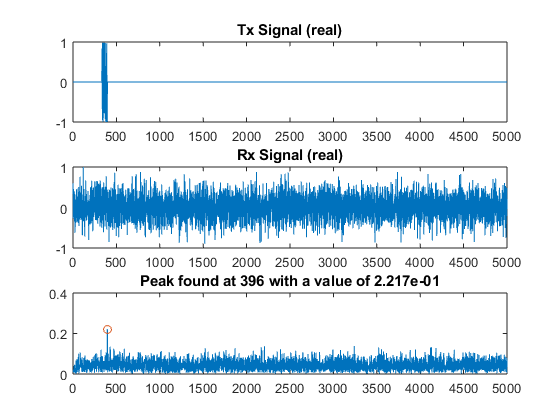

pulse_detector_reference;

## Simulate model and compare results to reference

% Simulate model in fixed-point or floating-point
fxpt_mode = true;
if fxpt_mode  % fixed-point
    DT_input = fixdt(1,16,14);
    DT_filter = fixdt(1,18,15);
    DT_power = fixdt(1,18,11);
else  % floating-point
    DT_input = 'double';
    DT_filter = 'double';
    DT_power = 'double';
end
DT_coeff = fixdt(1,18); % coeff is treated as double if input is double

if iscolumn(CorrFilter)
    CorrFilter = transpose(CorrFilter); % need row vector for filter block
end
SimTime = length(RxSignal) + WindowLen + 30;

% Simulate model
slout = sim('pulse_detector_v3_3');


% Correlation filter output
FilterOutSL = getLogged(slout,'filter_out');
FilterValid = getLogged(slout,'filter_valid');
FilterOutSL = FilterOutSL(FilterValid);
compareData(real(FilterOut),real(FilterOutSL),{2 3 1},'ML vs SL correlator output (re)');


Maximum error for ML vs SL correlator output (re) out of 5000 values
 8.466701e-06 (absolute), 3.828768e-03 (percentage)


compareData(imag(FilterOut),imag(FilterOutSL),{2 3 2},'ML vs SL correlator output (im)');


Maximum error for ML vs SL correlator output (im) out of 5000 values
 1.423705e-05 (absolute), 1.130064e-02 (percentage)


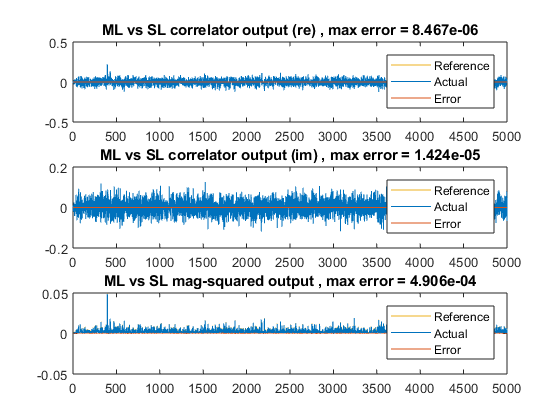


Maximum error for ML vs SL mag-squared output out of 5000 values
 4.906135e-04 (absolute), 9.977731e-01 (percentage)



% Magnitude squared output
MagSqSL = getLogged(slout,'mag_sq_out');
MagSqSL = MagSqSL(FilterValid);
compareData(MagSqOut,MagSqSL,{2 3 3},'ML vs SL mag-squared output');


% Peak value
MidSampleSL = getLogged(slout,'mid_sample');
Detected = getLogged(slout,'detected');
PeakSL = double(MidSampleSL(Detected>0));

fprintf('\nPeak location = %d, magnitude = %.3d using global max\n',location,peak);


Peak location = 396, magnitude = 2.217e-01 using global max


fprintf('Peak location = %d, mag-squared = %.3d using local max\n',location_2,peak_2);

Peak location = 396, mag-squared = 4.917e-02 using local max


fprintf('Peak mag-squared from Simulink = %.3d, error = %.3d\n',PeakSL,abs(peak_2-PeakSL));

Peak mag-squared from Simulink = 4.883e-02, error = 3.427e-04
